clear all;
warning 'off';

## MPC variables pre calculations

m_cart = 0.493;
m_pend = 0.312;
I_pend = 0.00024;
l = 0.04;
f = 0.01;
k_T = 0.11;
R = 10;
r = 0.0335;
g = 9.8;

d = 0.165;
Iw = 0.00002805*3;
Ip = 0.001972;
Ts = 0.005;

A = [-(I_pend+m_pend*(l^2))*f/(I_pend*(m_cart+m_pend)+m_cart*m_pend*(l^2)) (m_pend^2)*g*(l^2)/(I_pend*(m_cart+m_pend) + m_cart*m_pend*(l^2)) 0;
    0 0 1;
    -m_pend*l*f/(I_pend*(m_cart+m_pend)+m_cart*m_pend*(l^2)) m_pend*g*l*(m_cart+m_pend)/(I_pend*(m_cart+m_pend) + m_cart*m_pend*(l^2)) 0];

B = (2*k_T/r/R)*[(I_pend+m_pend*(l^2))/(I_pend*(m_cart+m_pend) + m_cart*m_pend*(l^2)); 0; m_pend*l/(I_pend*(m_cart+m_pend) + m_cart*m_pend*(l^2))];

C = eye(3);
D = zeros(3,1);
Q = [100 0 0 ; 0 10 0 ; 0 0 10];
R = [0.1];
K = lqr(A,B,Q,R);


A2 = [0 1;0 0];
B2 = (k_T/R)*[0;(d)/(r*(2*Iw+Ip))/1000];
C2 = eye(2);
D2 = zeros(2,1);
sys2 = ss(A2,B2,C2,D2,Ts);
A2 = sys2.A;
B2 = sys2.B;


$$\dot{x} = Ax + BK(r_{mpc}-y) = Ax + BK(r_{mpc}-Cx) 
\\\Rightarrow \dot{x} = (A-BKC)x+BKr_{mpc}
\\y = Cx + DK(r_{mpc}-y) = (C-DKC)x + DKr_{mpc} = Cx

$$


Closed loop plant:


$$A_d = A - Bk
\\B_d = Bk
\\C_d = C-DKC = C
\\D_d = D = 0$$


sys_d = c2d(ss(A,B,C,D),Ts);
Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;
%}


R = 100;

Q = [10^3 0 0 ; 0 10^4 0;0 0 1];
N = 10;  %This is the horizon for MPC
Qbar = [];
Rbar = [];
Kbar = [];
r = [10;0;0;0];
refbar = [];
Gbar = [];
Sx = []; 
Sx2 = [];
Sr = [];
hr=[];
Sr2 = [];
Y = [0;0;0;0];
W2_0 = [];
X_lims = [5,30/180*pi,1000];


for ii = 1:N
    Qbar = blkdiag(Qbar,Q);
    Rbar = blkdiag(Rbar,R);
    
    Sx = blkdiag(Sx,Ad^(ii));
    if ii==1
        hr = [Bd];
    else 
        hr = [Ad^(ii-1)*Bd hr];
    end
    
    Sr = [Sr;[hr  zeros(3,N -ii)]];
    
    W2_0 = [W2_0;X_lims'];
end


G1 = [-eye(N);eye(N)];
Nbar = Kbar*Sx2;
Fr = -2*Qbar*Sr;
Fx = 2*Sx'*Qbar*Sr;
H = 2*(Sr'*Qbar*Sr + Rbar);
G2 = [-Sr;Sr];
G = [G1;G2];
W1 = ones(2*N,1)*12;

options = optimoptions('quadprog');
options.Display = 'none';
ii = 1;
T = 50;

rlist = [];
theta_list = [];
output_list =[];

U = 0;
ref_V = 0;
ref_theta = 0;
ref_thetad = 0;
X1 = [1,0,0]';
X2 = [0;0];
global XY;
XY = readmatrix("Path_mpc.csv");
p_XY = XY(1,:);
dt = Ts;
p = [p_XY];
rateMPC = rateControl(5);
index = 0;
plot_xy = [];
plot_theta = [];
index = 0;

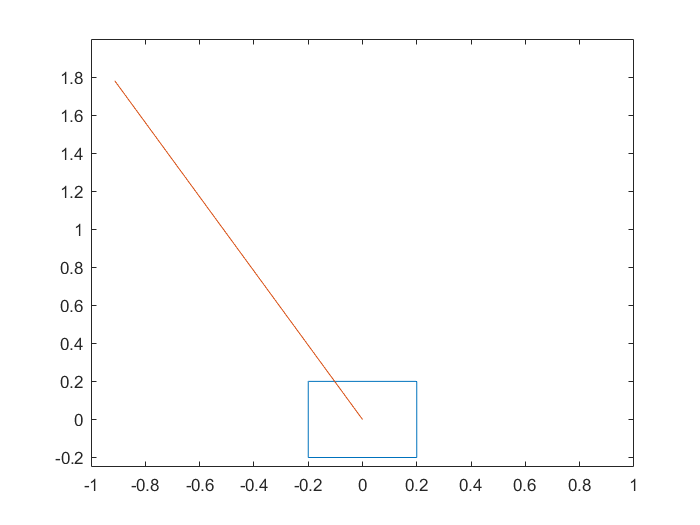

Umpc = [];
Theta = [];
Uleft = [];
Uright = [];
while ( index + N < 2222)
    X0 = X1;
    plot_theta = [plot_theta;X0(2)];
    psi = X2(1);
    refbar = [];
    X0bar = [];
    heading = [X0(1)*cos(psi),X0(1)*sin(psi)];
    
    p_XY = [X0(1)*cos(psi) + p_XY(1), X0(1)*sin(psi) + p_XY(2)];
    index = nearestNextPoint(p_XY,index,N);
    des_XY = XY(index,:);
    d_XY = (des_XY-p_XY);
    
    des_psi = atan2(-d_XY(2),d_XY(1));
    for kk = 1:N
        
        
        if (kk==1)
            ref_V =  norm(XY(index+1,:)- p_XY);
            
        else
            ref_V = norm(XY(index+kk+1,:) - XY(index+kk,:));
        end
        
        refbar = [refbar;ref_V;ref_theta;ref_thetad];
        X0bar = [X0bar;X0];
    end
    W = [W1;W2_0 + Sx*X0bar;W2_0 - Sx*X0bar];
    f = refbar'*Fr + X0bar'*Fx;
    [Z,~,exit_flag,~] = quadprog(H,f,G,W,[],[],[],[],[],options);  %Here is the magic!
    ifexecuted_flag = exit_flag;
    umpc = Z(1);
    X1 = Ad*X0 + Bd*umpc;
    
    
    Umpc = [Umpc;umpc];
    Theta = [Theta; X1(2)];
    err_psi = des_psi - X2(1);
    u_diff = -0.075*err_psi;
    X2 = A2*X2 + B2*u_diff;
    
    X2(1);
    p = [p;p_XY];
    
    ii = ii +1;
    
    theta = X1(2);
    
    plot(XY(:,1),XY(:,2),'k')
    figure(1);hold('on');             
    scatter(p_XY(1),p_XY(2));
    legend("Track","Actual position of Bot")
    hold('off');
    Uleft = [Uleft;(2*umpc+u_diff)/2];
    
    Uright = [Uright;(2*umpc-u_diff)/2];
    figure(2);hold('off');
    plot([0.2,0.2,-0.2,-0.2,0.2],[-0.2,0.2,0.2,-0.2,-0.2]);hold('on');
    plot([0,2*sin(theta)],[0,2*cos(theta)]);hold('off');
    xlim([-1,1]);
    ylim([-0.25,2]);
    drawnow()    
end

figure(10)
length(Theta)

ans = 187

time_data = linspace(0,length(Theta)*Ts,length(Theta))

time_data =          0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0855    0.0905    0.0955    0.1005    0.1056    0.1106    0.1156    0.1206    0.1257    0.1307    0.1357    0.1408    0.1458    0.1508    0.1558    0.1609    0.1659    0.1709    0.1759    0.1810    0.1860    0.1910    0.1960    0.2011    0.2061    0.2111    0.2162    0.2212    0.2262    0.2312    0.2363    0.2413    0.2463


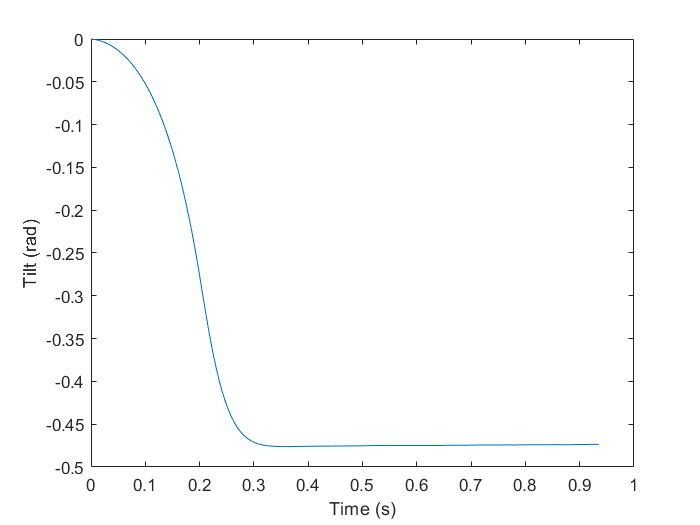

plot(time_data,Theta);
xlabel("Time (s)");
ylabel("Tilt (rad)");

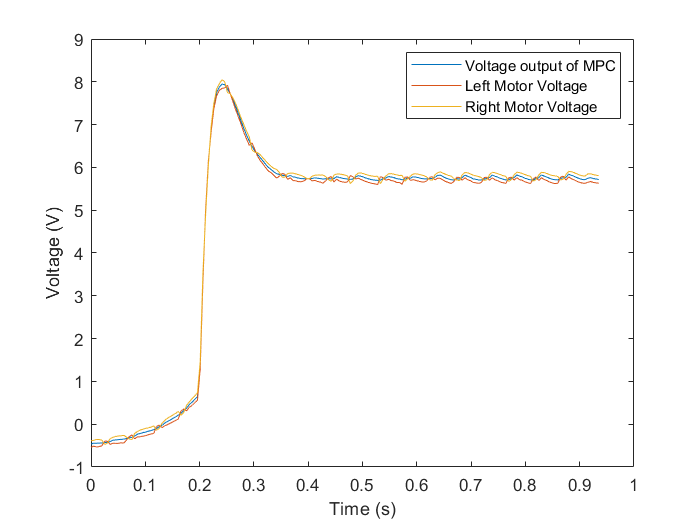



plot(time_data,Umpc);
hold('on');
plot(time_data,Uleft);
plot(time_data,Uright)
xlabel("Time (s)");
ylabel("Voltage (V)");
legend("Voltage output of MPC","Left Motor Voltage","Right Motor Voltage")

function next_index = nearestNextPoint(current_pose,index,N)
    global XY;
    next_index = index;
    n = size(XY,1) - N-1;
    dist = norm(current_pose - XY(index+1,:));
    for i = index+1 : n
        if(norm(current_pose - XY(i,:)) > dist)
            next_index = i-1;
            break;
        else
            dist = norm(current_pose - XY(i,:));
        end
    end
end
